clear;
close all;

%Choose the k value , i.e. for 5 k values we will get 5 plots.
set_k = 5;

filename1 ='/Users/parisha/Desktop/AT-ML/ECE6604-MP1/Data sets/Linear regression/P1-data1.txt';
delimiter = ',';


A = importdata(filename1);
inputs_A= A(:,1);
outputs_A = A(:,2);


filename2 ='/Users/parisha/Desktop/AT-ML/ECE6604-MP1/Data sets/Linear regression/P1-data2.txt';



B = importdata(filename2);
inputs_B= B(:,1);
outputs_B = B(:,2);





x_test_A = linspace(min(inputs_A),max(inputs_A),100);
x_test_B = linspace(min(inputs_B),max(inputs_B),200);

Distance_A = zeros(length(x_test_A),length(inputs_A));
Distance_B= zeros(length(x_test_B),length(inputs_B));

%MAke a distance matrix for Dataset 1
for i=1:length(x_test_A)
    for j=1:length(inputs_A)
        Distance_A(i,j) = sqrt((x_test_A(i) - inputs_A(j)).^2);
    end
end

%MAke a distance matrix for Dataset2

for i=1:length(x_test_B)
    for j=1:length(inputs_B)
        Distance_B(i,j) = sqrt((x_test_B(i) - inputs_B(j)).^2);
    end
end
% choose the number of nearest neighbors k

for k=set_k

[b,k_index_A] = mink(Distance_A,k,2);
b
k_index_A

y_knn_A = zeros(length(outputs_A),1);

for i=1:length(x_test_A)
    sum_a=0;
    for j=1:k
        sum_a = sum_a + outputs_A(k_index_A(i,j));
        
    end
    y_knn_A(i,1) = sum_a/k;
end



[c,k_index_B] = mink(Distance_B,k,2)
y_knn_B = zeros(length(outputs_B),1);

for i=1:length(x_test_B)
    sum_b=0;
    for j=1:k
        sum_b = sum_b + outputs_B(k_index_B(i,j));
    end
    y_knn_B(i,1) = sum_b/k;
end

plot(inputs_A,outputs_A,'*',inputs_B,outputs_B,'.')
hold on
plot(x_test_A,y_knn_A,'b');
hold on
plot(x_test_B,y_knn_B,'r');
hold on

end

b =          0    0.0096    0.0277    0.0325    0.0433
    0.0120    0.0211    0.0520    0.0703    0.0927
    0.0055    0.0330    0.0630    0.0662    0.0685
    0.0058    0.0175    0.0197    0.0270    0.0480
    0.0083    0.0102    0.0131    0.0132    0.0528
    0.0026    0.0237    0.0346    0.0930    0.1076
    0.0617    0.0659    0.1212    0.1761    0.1972
    0.0328    0.0523    0.0847    0.0914    0.1120
    0.0147    0.0495    0.0560    0.0592    0.0615
    0.0010    0.0405    0.0725    0.1022    0.1588


k_index_A =     71    74     6    86    43
    78    58    27    14    76
    12    37    93    48    90
    46    21     1    85    65
    77     7     9    87    40
    30    89     2    44    84
    69    84    17    30    89
    53    17    20    51    36
    15    13    52    79    36
    28    72    81     5    15


c =          0    0.0500    0.1000    0.1500    0.2000
    0.0003    0.0497    0.0503    0.0997    0.1497
    0.0005    0.0495    0.0505    0.0995    0.1005
    0.0008    0.0492    0.0508    0.0992    0.1008
    0.0010    0.0490    0.0510    0.0990    0.1010
    0.0013    0.0487    0.0513    0.0987    0.1013
    0.0015    0.0485    0.0515    0.0985    0.1015
    0.0018    0.0482    0.0518    0.0982    0.1018
    0.0020    0.0480    0.0520    0.0980    0.1020
    0.0023    0.0477    0.0523    0.0977    0.1023


k_index_B =      1     2     3     4     5
     2     3     1     4     5
     3     4     2     5     1
     4     5     3     6     2
     5     6     4     7     3
     6     7     5     8     4
     7     8     6     9     5
     8     9     7    10     6
     9    10     8    11     7
    10    11     9    12     8


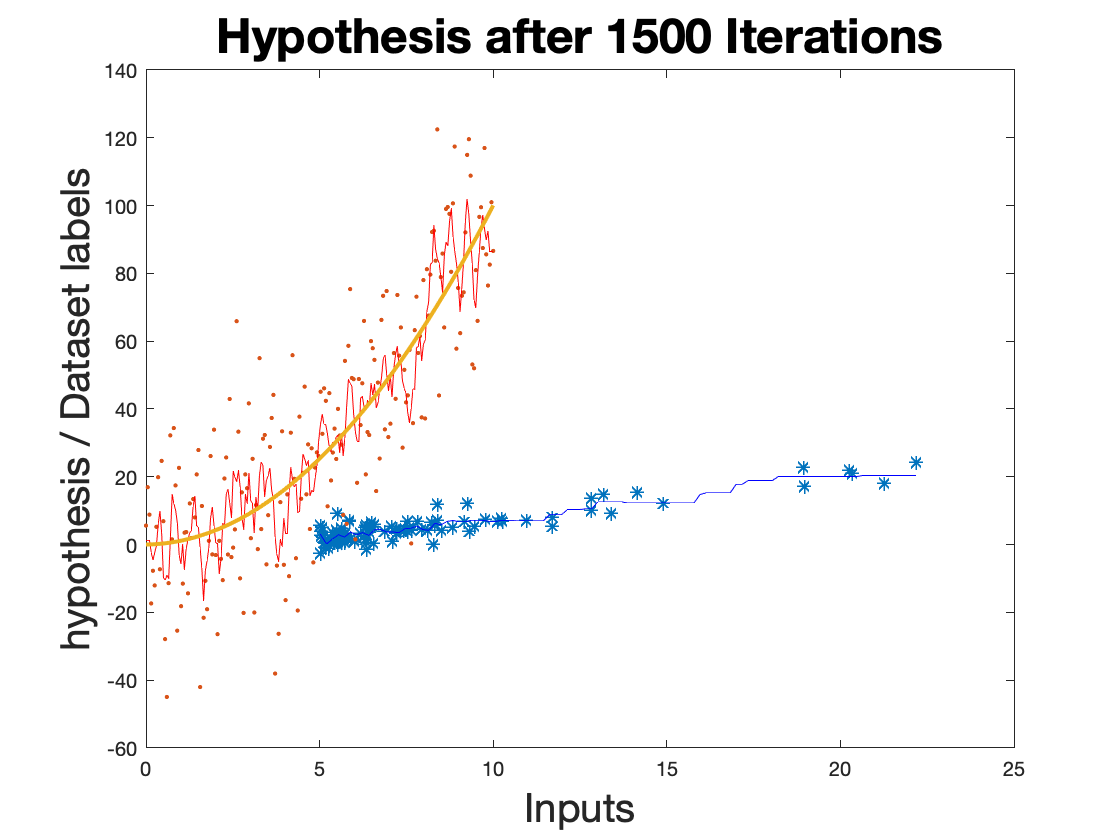

title('kNN hypothesis for both Datasets',"FontSize",24)
xlabel('Inputs',"FontSize",20)
ylabel('Outputs',"FontSize",20)


filename ='/Users/parisha/Desktop/AT-ML/ECE6604-MP1/Data sets/Linear regression/P1-data2.txt';
delimiter = ',';

A = importdata(filename);
inputs= A(:,1);
outputs = A(:,2);
B_0=0;
B_1=0;
B_2=0;
Beta = [B_0 B_1 B_2];
iterations = 20;
learn_rate = 10^-6; 
Beta_update = zeros(length(inputs),3);
input_1x =[ones(1,length(inputs)); transpose(inputs)];
input_2x =[ones(1,length(inputs)); transpose(inputs); transpose(inputs).^2];
y_caps = zeros(1,length(inputs));
for itr = 1:iterations
    
    %part 1 to find y_cap - yi
    
    for i=1:length(inputs)
        
        y_caps(i) = B_0 + B_1 * inputs(i) +  B_2 * inputs(i)* inputs(i);
        error= y_caps(i) - outputs(i);
        B_0 = B_0 - (learn_rate *error);
        B_1 = B_1 - (learn_rate *error*inputs(i));
        B_2 = B_2- (learn_rate *error*inputs(i)*inputs(i));
        Beta_update(i,:) = [B_0 B_1 B_2];
        
        
    end
    

end
hyp = Beta_update(length(inputs),:) * input_2x;
hold on;
plot(inputs,hyp,"LineWidth",2);
title('Hypothesis after 1500 Iterations',"FontSize",24);
ylabel('hypothesis / Dataset labels',"FontSize",20);
xlabel('Inputs',"FontSize",20);
hold on

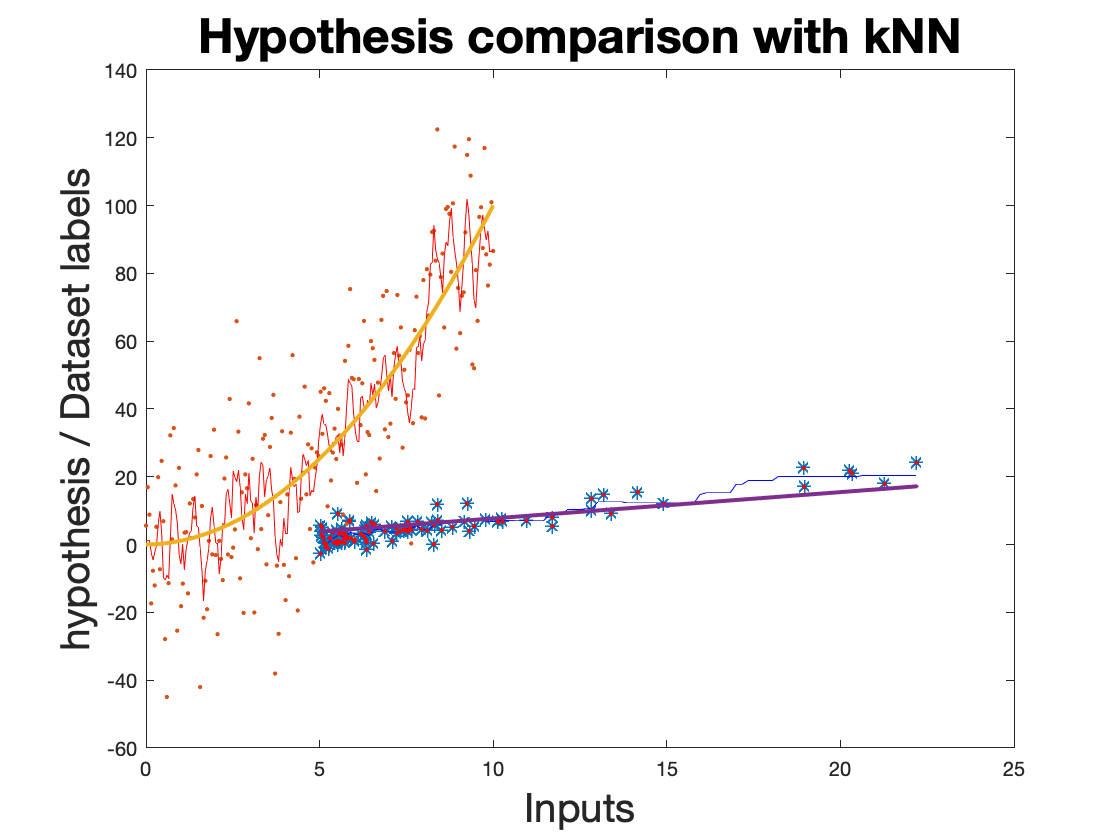

filename ='/Users/parisha/Desktop/AT-ML/ECE6604-MP1/Data sets/Linear regression/P1-data1.txt';
delimiter = ',';

A = importdata(filename);
inputs= A(:,1);
outputs = A(:,2);
B_0=0;
B_1=0;
Beta = [B_0 B_1];
iterations = 1500;
learn_rate = 0.01; 
Beta_update = zeros(length(inputs),2);
learn_rate2 = 10^-6;
B_0=0;
B_1=0;
input_1x =[ones(1,93); transpose(inputs)];


for itr = 1:iterations
    
    %part 1 to find y_cap - yi
    
    for i=1:length(inputs) 
        y_caps(i) = B_0 + B_1 * inputs(i);
        error= y_caps(i) - outputs(i);
        B_0 = B_0 - (learn_rate2 *error);
        B_1 = B_1 - (learn_rate2 *error*inputs(i));
        Beta_update(i,:) = [B_0 B_1];
    end
    end
hyp2 = Beta_update(length(inputs),:) * input_1x;
plot(inputs,outputs,'r.');
title('Hypothesis comparison with kNN')
hold on;
plot(inputs,hyp2,"LineWidth",2);

hold off;